# Parameter Estimation for Discrete-SIR models

% load('Data/India.mat')
% ydata = [Cases-Recovered-Death;Recovered; Death];
% 
% % ydata = ydata(:, 10:end)';
% ydata = [ydata(1,430:end-15); ydata(2,430:end-15); ydata(3,430:end-15)];
% CasesAct = Cases(430:end-15);

% load('../Data/Colombia.mat')
% ydata = [Cases-Recovered-Dead;Recovered; Dead];
% time = 150:420;
% ydata = [ydata(1,time); ydata(2,time); ydata(3,time)];
% ydata(:,145) = median(ydata(:, 130:140)');
% CasesAct = Cases(1,time);

% load('../Data/Germany.mat')
% ydata = [Cases-Recovered-Death;Recovered; Death];
% time = 120:480;
% ydata = [ydata(1,time); ydata(2,time); ydata(3,time)];
% % ydata(:,265) = median(ydata(:, 230:260)');
% CasesAct = Cases(1,time);


load('../Data/Korea.mat')
ydata = [Cases-Recovered-Death;Recovered; Death];

% ydata = ydata(:, 10:end)';
time = 30:260;
ydata = [ydata(1,time); ydata(2,time); ydata(3,time)];
CasesAct = Cases(1,time);

syms S_f(t) S_q(t) I_f(t) I_q(t) I_j(t) R(t) R_j(t)
syms alpha lambda z mu theta beta nu gamma

N = S_f + S_q + I_f + I_q + I_j + R + R_j;

aleph = 1+nu*I_f/(I_f + S_f)

$$aleph(t) = \frac{\nu \,I_{f}\left(t\right)}{I_{f}\left(t\right)+S_{f}\left(t\right)}+1$$


% P1 = 1-(1 - (I_f/N)^aleph)^z;
P1 = 1-(1-1/(S_f+1))^((z*I_f)*(S_f/N)^aleph);

ode1 = diff(S_f) == -S_f*(beta*P1 + lambda) + S_q*alpha + mu*(R_j + R);
ode2 = diff(S_q) ==  lambda*S_f - S_q*alpha;
ode3 = diff(I_f) == S_f*beta*P1 + alpha* I_q - I_f*(gamma + theta + lambda);
ode4 = diff(I_q) == -I_q*(alpha + gamma + theta) + I_f*lambda;
ode5 = diff(I_j) == theta*(I_q + I_f) - gamma*I_j;
ode6 = diff(R) == (I_q + I_f)*gamma - mu*R;
ode7 = diff(R_j) == I_j*gamma - mu*R_j;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7];
vars = [I_j R_j S_f S_q I_f I_q R];

opts = odeset('NonNegative',1:7,'AbsTol',1e-3,'RelTol',1e-3);


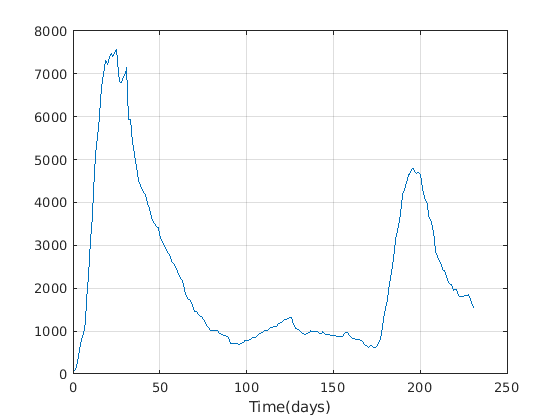

VarNames = {'S_f','S_q','I_f','I_q','I_j','R','R_j'};
OutNames = {'S_f','S_q','I_f','I_q','I_j','R','R_j'};
% ParNames = {'\lambda','\alpha','\mu', '\theta', '\gamma', '\nu', 'z'};

% FullNames = [VarNames,ParNames];
% 
% Colombia
% Range1 = [
%     5e5 5e7;            %S_f
%     5e1 5e6;            %S_q    
%     0 1e4;                 %I_f                
%     0 2.5e4;                    %I_q
%     ydata(1,1)*0.2 ydata(1,1)*1.2;  %I_j
%     0 2.5e4;                 %R
%     ydata(2,1) ydata(2,1);  %R_j
%     ];

% % Colombia
% Range1 = [
%     ydata(1,1) ydata(1,1);  %I_j
%     ydata(2,1) ydata(2,1);  %R_j
%     2e7 3e7;            %S_f
%     1e7 2e7 ;            %S_q    
%     5e3 10e6;                 %I_f                
%     5e3 10e6;                    %I_q
%     5e3 10e6;                 %R
%     ];


% % % %Korea
Range1 = [    
    ydata(1,1) ydata(1,1);  %I_j    
    ydata(2,1) ydata(2,1);  %R_j
    5.1e7 5.1e7;            %S_f
    0 1;                    %S_q    
    0 1000;                 %I_f                
    0 1;                    %I_q
    0 1000;                 %R
    ];

Range2 = [            
            0 1; %alpha
            0 1; %beta
            0 1; %gamma 
            0 1; %lambda 
            0 0.01; %mu 
            0 1000; %nu             
            0 1; %theta
            0 30%z 
];

Range = [Range1; Range2];

D = length(ydata(1,:));
Domain = [0 D-1];
xdata = 0:D-1;

figure
plot(ydata(1,:))
grid on
xlabel("Time(days)")

outs = 1;
[T,~] = gsua_dpmat(odes,vars,[0 length(xdata)],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccccccccc} I_{j}\left(t\right) & R_{j}\left(t\right) & S_{f}\left(t\right) & S_{q}\left(t\right) & I_{f}\left(t\right) & I_{q}\left(t\right) & R\left(t\right) & \alpha & \beta & \gamma & \lambda & \mu & \nu & \theta & z \end{array}\right)$$

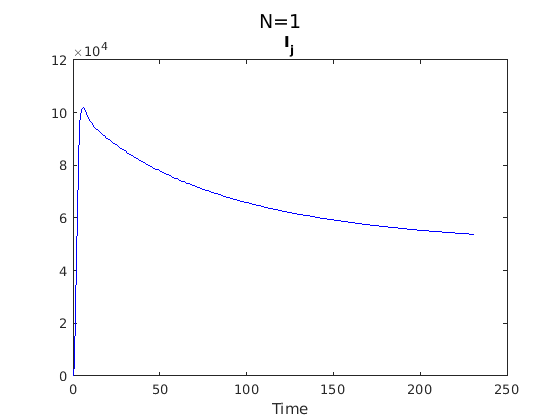

 gsua_eval(T.Nominal, T);

## Parameter estimation model simple, complex and classic probabilities

close all
 
ModelNames = ["Simple", "Complex", "Classic"];

T_save = cell(2,1);     
N = 1;
extra = struct();
Parameters = [];
Res = [];
 
       
    Opt = optimoptions('lsqcurvefit', 'UseParallel', false,'MaxFunctionEvaluations', 30000, ...
        'MaxIterations', 3000, 'Display','off');
    Solver = "lsqc"; 
%     parfor j = 1:N
    for j = 1:N
        [T_aux, Res_aux] = gsua_pe(T, xdata, ydata(1,:),...
            'solver', Solver,'N', 1,'opt', Opt,'save', false);
        Parameters(:,j) = T_aux.Estlsqc;
        Res(j) = Res_aux;
    end
    
    [Res, idx] = sort(Res);
    Parameters = Parameters(:,idx);     
    T_save{i}.Nominal = Parameters(:,1);
%     save("ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCases" + ModelNames(i), "Res",  "Parameters")
    
    figure
    gsua_eval(Parameters(:,1), T, xdata, ydata(1,:));
    suptitle(ModelNames(i) + " residual: " + Res(1))

Setting environment to work with user-defined function


Generating a valid matrix for estimations
Generating a valid matrix for estimations
Generating a valid matrix for estimations
Generating a valid matrix for estimations
Generating a valid matrix for estimations
Generating a valid matrix for estimations
Generating a valid matrix for estimations
Generating a valid matrix for estimations
Estimation 1

ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3885e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3919e+07


ans =

   4.3988e+07


ans =

   4.3988e+07


ans =

   4.3988e+07


ans =

   4.3988e+07


ans =


load("ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCasesSimple")
T.Simple = Parameters(:,1);
load("ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCasesComplex")
T.Complex = Parameters(:,1);
load("ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCasesClassic")
T.Clas = Parameters(:,1);
T

% load("ResultsCovid/Estimations_korea_Aleph_osc_ActualCasesSimple.mat")
% T.Simple = Parameters(:,1);
% load("ResultsCovid/Estimations_korea_Aleph_osc_ActualCasesComplex.mat")
% T.Complex = Parameters(:,1);
% load("ResultsCovid/Estimations_korea_Aleph_osc_ActualCasesClassic.mat")
% T.Clas = Parameters(:,1);
% T


% Files = ["ResultsCovid/Estimations_korea_Aleph_osc_ActualCasesSimple.mat",...
%         "ResultsCovid/Estimations_korea_Aleph_osc_ActualCasesComplex.mat",...
%         "ResultsCovid/Estimations_korea_Aleph_osc_ActualCasesClassic.mat"];
    
Files = ["ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCasesSimple.mat",...
        "ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCasesComplex.mat",...
        "ResultsCovid/Estimations_Colombia_Aleph_osc_ActualCasesClassic.mat"];
Titles = ["Infected with \psi(t)", "Infected with \phi(t)",...
          "Infected with classic"];

counter = 1;
figure

for k = 1:3
    load(Files(k))
    N = size(Res, 1);
    ysim = zeros(N, 1, D);
    for i = 1:N
        ysim(i,:,:) = gsua_deval(Parameters(:,i)', T_save{k}, xdata);
        Res(i) = immse(squeeze(ysim(i,:,:)), ydata(1,:)');
%         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
    end
    
    [~, Idx] = sort(Res);
    IdxSims(k) = Idx(1);
    
    for j = 1:1        
        subplot(3,1,counter)
        plot(squeeze(ysim(IdxSims(k), j, :))', 'r','LineWidth',2); 
        hold on
        plot(ydata(j,:)','--k','LineWidth',2)
        grid on
%         title(Titles(counter))
        counter = counter +1;
        xlim([0 length(ydata)]);
    end
end

legend({"Simulation", "Real data"}, 'location','best')
xlabel("Time in days")
load(Files(1))
disp("S(0): " + Parameters(1,IdxSims(1)) + ", gamma: " + Parameters(2,IdxSims(1)) +...
    ", mu: " + Parameters(3,IdxSims(1)) + ", z: "+ Parameters(4,IdxSims(1)))
load(Files(2))
disp("S(0): " + Parameters(1,IdxSims(2)) + ", gamma: " + Parameters(2,IdxSims(2)) +...
    ", mu: " + Parameters(3,IdxSims(2)) + ", z: "+ Parameters(4,IdxSims(2)))
load(Files(3))
disp("S(0): " + Parameters(1,IdxSims(3)) + ", gamma: " + Parameters(2,IdxSims(3)) +...
    ", mu: " + Parameters(3,IdxSims(3)) + ", z: "+ Parameters(4,IdxSims(3)))

## Equilibriums

% D2 = [10000, 10000];
% for i = 1:2
%     load(Files(i))    
%     T_save{i}.Properties.CustomProperties.Domain(2) = D2(i);
%     T_save{i}.Properties.CustomProperties.output = 1:3;
%     figure
%     y = gsua_eval(Parameters(:,IdxSims(k)), T_save{i}, 0:D2(i));
%     disp("S = " + y(1,end,1) + " I = " + y(1,end,2) + " R = " + y(1,end,3) + " N = " + sum(y(:,1,:)))
% end

## Identifiability analisys

% T_ia = cell(2,1);  
% disp(ModelNames(1))
% T_ia{1} = gsua_ia(T_save{1},Parameters,false,false);

% disp(ModelNames(2))
% T_ia{2} = gsua_ia(T_save{2},Parameters,false,false);

% disp(ModelNames(3))
% T_ia{3} = gsua_ia(T_save{3},Parameters,false,false);

**Sensitivity analisys for estimation intervals**

N = 200000;
M = gsua_dmatrix(T_save{1}, N, 'Method', 'Sobol');

T_save{1} = gsua_sa(M,T_save{1});
sum(T_save{1}.Si)/sum(abs(T_save{1}.Si))
figure
gsua_plot('Pie',T_save{1},T_save{1}.STi)
figure
gsua_plot('Bar',T_save{1},T_save{1}.STi)

M = gsua_dmatrix(T_save{2}, N, 'Method', 'Sobol');
T_save{2} = gsua_sa(M,T_save{2});
sum(T_save{2}.Si)/sum(abs(T_save{2}.Si))
figure
gsua_plot('Pie',T_save{2},T_save{2}.STi)
figure
gsua_plot('Bar',T_save{2},T_save{2}.STi)

M = gsua_dmatrix(T_save{3}, N, 'Method', 'Sobol');
T_save{3} = gsua_sa(M,T_save{3});

sum(T_save{3}.Si)/sum(abs(T_save{3}.Si))
figure
gsua_plot('Pie',T_save{3},T_save{3}.STi)
figure
gsua_plot('Bar',T_save{3},T_save{3}.STi)

N = 1000;
M = gsua_dmatrix(T_ia{1}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{1},'xdata', xdata, 'ynom', ydata, 'parallel', false);

% N = 10000;
% 
% M = gsua_dmatrix(T_ia{1}, N, 'Method', 'Sobol');
% T_ia{1} = gsua_sa(M,T_ia{1});
% sum(T_ia{1}.Si)/sum(abs(T_ia{1}.Si))
% figure
% gsua_plot('Pie',T_ia{1},T_ia{1}.STi)
% figure
% gsua_plot('Bar',T_ia{1},T_ia{1}.STi)
% M = gsua_dmatrix(T_ia{2}, N, 'Method', 'Sobol');
% T_ia{2} = gsua_sa(M,T_ia{2});
% sum(T_ia{2}.Si)/sum(abs(T_ia{2}.Si))
% figure
% gsua_plot('Pie',T_ia{2},T_ia{2}.STi)
% figure
% gsua_plot('Bar',T_ia{2},T_ia{2}.STi)
% M = gsua_dmatrix(T_ia{3}, N, 'Method', 'Sobol');
% T_ia{3} = gsua_sa(M,T_ia{3});
% sum(T_ia{3}.Si)/sum(abs(T_ia{3}.Si))
% figure
% gsua_plot('Pie',T_ia{3},T_ia{3}.STi)
% figure
% gsua_plot('Bar',T_ia{3},T_ia{3}.STi)
% M = gsua_dmatrix(T_ia{2}, N, 'Method','Sobol');  
% gsua_ua(M, T_ia{2},'xdata', xdata, 'ynom', ydata, 'parallel', false);